`【例`**2-1**`】变量定义举例如下：`  

**    A a king**  

`在`**MATLAB**`中的变量不需要事先定义，在遇见新的变量名时，`**MATLAB**`会自动建立并且为其分配存储空间。如果遇见已经出现的变量，会重新为其分配空间。`

`【例`**2-2**`】数值举例如下：`  

**   109   -27   6e-21**

**   0.01   5i    6+2i**  

  `所以我们可以直接把数值赋给变量，例如`a=7`。当然，还有三个函数需要我们认识，一个函数为`real()`函数，可以用来提取复数中的实部，另一个函数为`imag()`函数，可以用来提取复数的虚部，还有一个函数为`complex()`，可以用来生产一个复数。`  

`【例`**2-3**`】举例说明`**real()**`，`**imag()**`和`**complex()**`函数的使用。`

a = complex(2,9)
b = real(a)
c = imag(a)

`【例`**2-4**`】 变量的赋值举例如下：`  

a=[1 4 7]
B=abs(6+13i)
C=[]

`注：当表达式的结果赋给变量时，而没有定义变量。系统默认为`**ans**`。` 

 `【例`**2-5**`】先定义一个变量`**a**`，然后求出它的长度，接着用`**clear**`清除。举例如下：`

a=[1,2,3,4,5,6,7,8,9,10]

`下面对向量`**a**`进行长度的求解。`  

n=length(a)

`利用`**MATLAB**`中的`**who**`命令显示`**MATLAB**`中的变量名。`

who a

`下面利用`**clear**`清除变量，再查看变量。`  

clear a
who a

  **MATLAB**`的运行结果中就没有上面那句话了，证明变量清除成功了。`

  `【例`**2-6**`】我们先定义一个变量`**a=ones(10)**`，然后求`**a**`的长度，紧接着利用用`**clc**`命令清除命令行窗口。在`**MATLAB**`的命令行窗口输入以下命令：`

a=ones(10)
size(a)

`然后再在`**MATLAB**`的命令行窗口输入以下命令：`

clc

`【例`**2-7**`】首先画正弦曲线，然后利用`**clf**`清除图形。在`**MATLAB**`中首先运行以下命令：`

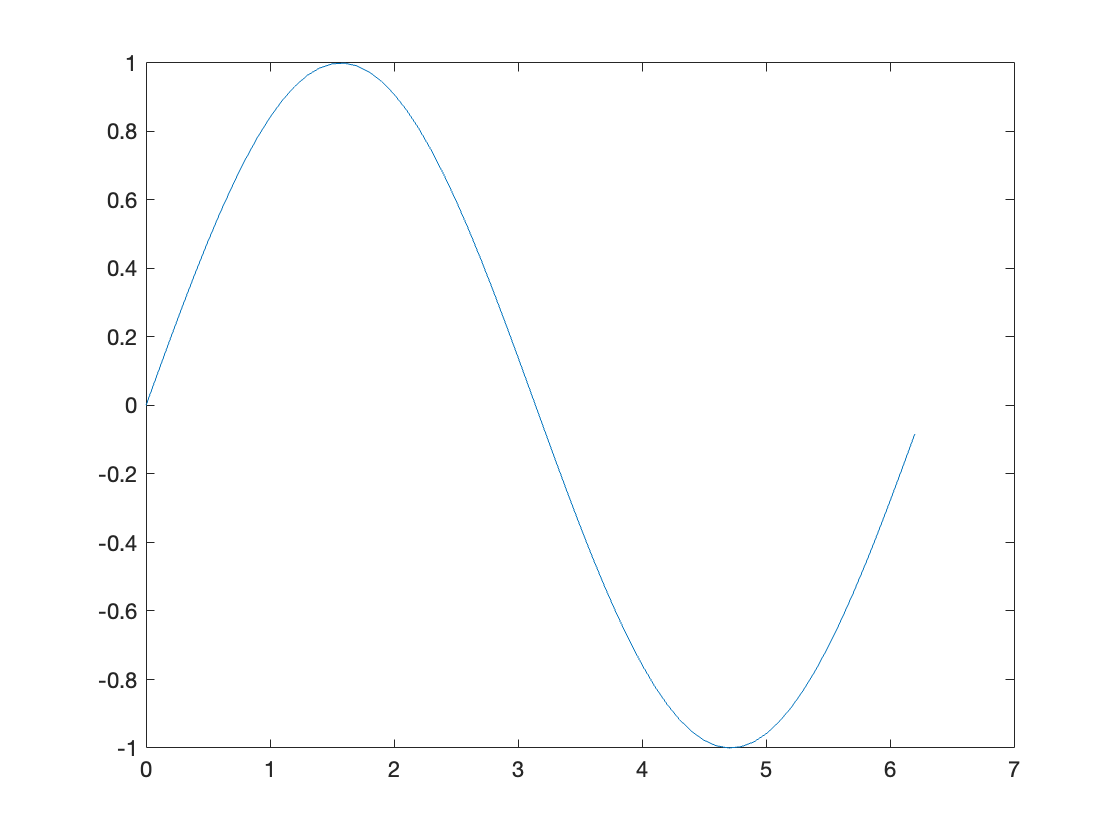

x = 0:0.1:2*pi;
plot(x,sin(x))

clf

`【例`**2-8**`】已知`**x=[1 2 3 2]**`， `**y=[1 1 1 1]**`，将其分别画在第`**1**`， `**2**`个子窗口中，代码如下：`  

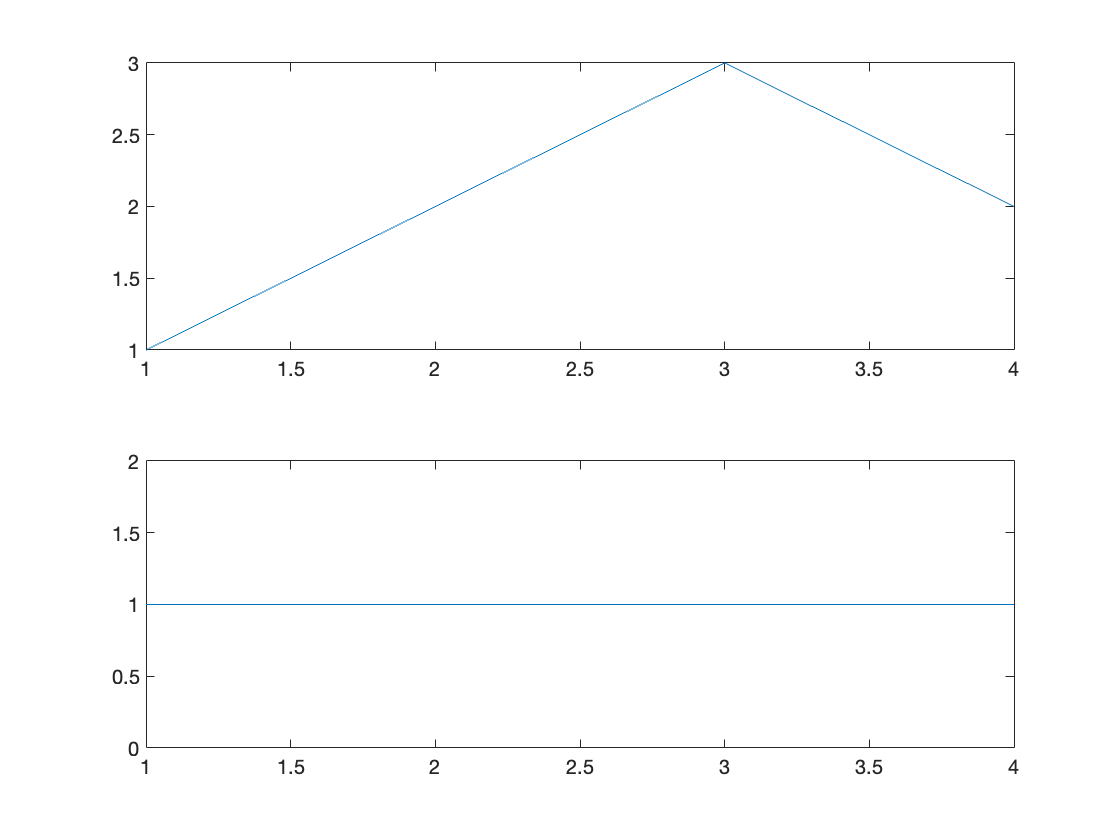

x=[1 2 3 2];
y=[1 1 1 1];
subplot(2,1,1)
plot(x)
subplot(2,1,2)
plot(y)

`【例`**2-9**`】已知一个结构数组`**A**`，查看其头信息。`**Matlab**`代码如下：`  

A = {[]}

A = 1×1 cell 数组
    {0×0 double}


whos A

  Name      Size            Bytes  Class    Attributes

  A         1x1               104  cell               



`【例`**2-10**`】已知`**x=-5**`，求它的绝对值。代码如下：`  

x=-5;
abs(x)

`【例`**2-11**`】已知`**x=9**`，对它开方，代码如下：`  

x=9;
sqrt(x)

`【例`**2-12**`】已知`**x=4.7**`，分别用`**round(x)**`、 `**fix(x)**`、 `**floor(x)**`、`**ceil(x)**`函数取`**4.7**`的整数。`

x=4.7;
round(x)
fix(x)
floor(x)
ceil(x)

`【例`**2-13**`】举例说明`**sign()**`函数的使用方法。`  

a=-1.2;
b=1.2;
c= 0;
sign(a)
sign(b)
sign(c)

`【例`**2-14**`】举例说明`**mod(x,y)**`和`**rem(x,y)**`的功能。`  

rem(18,4)
mod(18,4)
mod(15,-6)
rem(15,-6)

 `【例`**2-15**`】简单验证`**exp(x)**`、 `**log(x)**`、 `**log2(x)**`、 `**log10(x)**`这些函数的功能，再验证是否正确。代码如下：`

exp(2)
log(exp(2))
log2(16)
log10(100)

`【例`**2-16**`】计算`**a=1/3**`和`**a*3**`。 `**MATLAB**`代码如下：`  

a=1/3
a=a*3

`【例`**2-17**`】构造行向量和列向量，观察其在`**MATLAB**`中的表达形式。`  

a=[1,2,3,4,5]
b=[1;2;3;4;5]

`【例`**2-18**`】举例用`**‘**`： `**’**`生成向量。代码如下：`  

a=2:9
a=2:3:11

`【例`**2-19**`】利用`**linspace**`函数生成行向量。`  

x=linspace(1,100)

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


y= linspace(1,100,5)

y =     1.0000   25.7500   50.5000   75.2500  100.0000


`【例`**2-20**`】用`**logspace**`函数生成行向量，从例子我们可以看出，当数据足够大时候，系统用`**Inf**`代替。代码如下：`

X=logspace(3,1000,7)

  `【例`**2-21**`】设`**A=[1 2 3 5 6 8]**`，抽取其中的第`**1**`、 `**3**`、 `**5**`个元素作为新的向量`**B**`。 `**MATLAB**`的代码如下：`  

A = [1 2 3 5 6 8];
B = A([1 3 5])

`【例`**2-22**`】设`**A=[1 2 3 5 6 8]**`，抽取向量`**a=[1 3 5]**`所对应元素作为新的向量`**B**`。 `**MATLAB**`的代码如下：`  

A = [1 2 3 5 6 8];
a=[1 3 5];
B = A(a)

`【例`**2-23**`】设`**A=[1 2 3 5 6 8]**`，利用`**’:’**`抽取其中的第`**1**`、 `**3**`、 `**5**`个元素作为新的向量`**B**`。 `**MATLAB**`的代码如下：`  

A = [1 2 3 5 6 8];
B = A(1:2:5)

`利用直接输入法生产一个矩阵`**A**`。 `**MATLAB**`的代码如下：`

A = [1 2 3; 5 6 8]

  `【例`**2-25**`】利用`**ones()**`构造矩阵，其`**MATLAB**`代码为：`  

A = ones(3);
B = ones(2, 4);
A
B

`【例`**2-26**`】利用`**zeros ()**`构造矩阵，其`**MATLAB**`代码为：`  

A = zeros (3);
B = zeros (2, 4);
A
B

`【例`**2-27**`】利用`**eye ()**`构造矩阵，其`**MATLAB**`代码为：`  

A = eye (3);
B = eye (2, 4);
A
B

`【例`**2-28**`】利用`**rand()**`生成一个`**3*4**`在（`**0**`， `**1**`）区间均匀分布的矩阵`**Y**`，其`**MATLAB**`代码为：`  

Y = rand(3, 4);
Y

`【例`**2-29**`】利用`**rand()**`生成一个`**3*4**`在（`**-5**`， `**5**`）区间均匀分布的矩阵`**Y**`，其`**MATLAB**`代码为：`  

Y = 5 - 10 * rand(3, 4);
Y

`【例`**2-30**`】利用`**rand()**`生成一个`**3*4**`在（`**-5**`， `**5**`）区间均匀分布的随机整数矩阵`**Y**`，其`**MATLAB**`代码为：`  

Y = 5 - round(10*rand(3, 4));
Y

`【例`**2-31**`】利用`**rand()**`生成一个`**3*4**`在（`**-5**`， `**5**`）区间均匀分布的随机矩阵`**Y**`，且矩阵中元素精确到`**0.01**`，其`**MATLAB**`代码为：`  

Y = 5 - round(1000*rand(3, 4))/100;
Y

`【例`**2-32**`】利用`**randn ()**`一个`**3*4**`符合标准正态分布的随机矩阵`**Y**`，其`**MATLAB**`代码为：` 

Y = randn(3, 4);
Y

`【例`**2-33**`】利用`**randn()**`生成一个`**3*4**`符合均值为`**5**`，方差为`**9**`的正态分布的随机矩阵`**Y**`，其`**MATLAB**`代码为：`  

Y = 3 * rand(3, 4) + 5;
Y

`【例`**2-34**`】使用`**save**`函数连续保存多个变量到多个文件中。其`**MATLAB**`代码为：`  

file='data';
xstr='x';
% create var
for i=1:10
eval([xstr,num2str(i),'=',num2str(i),';'])
end
% save data
for i=1:10
save([file int2str(i)], [xstr int2str(i)]);
end

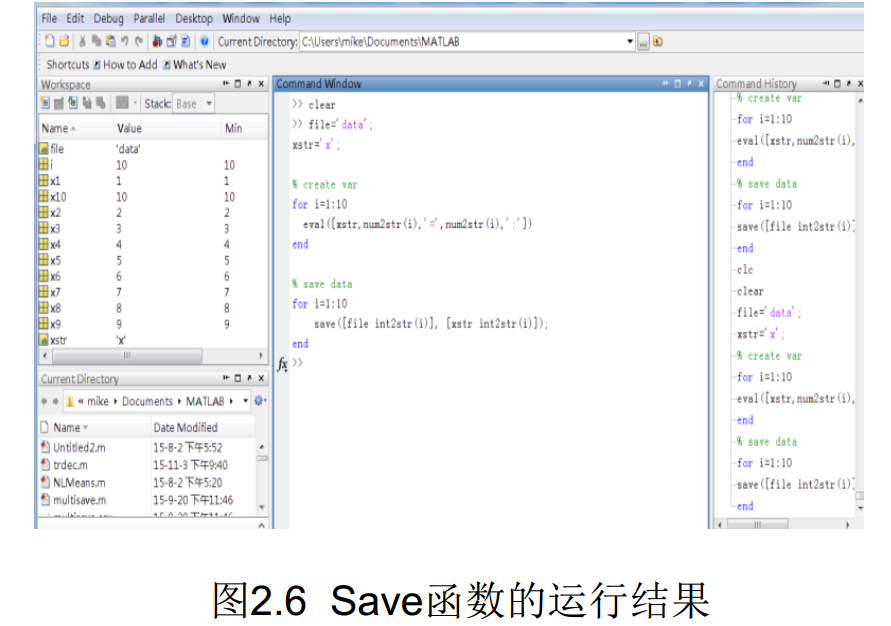

`【例`**2-35**`】使用`**load**`函数将上例中的变量在`**MATLAB**`中显示。其`**MATLAB**`代码为`  ：

file='data';
xstr='x';
% create var
for i=1:10
eval([xstr,num2str(i),'=',num2str(i),';'])
end
% load data
for i=1:10
load([file int2str(i)], [xstr int2str(i)]);
end

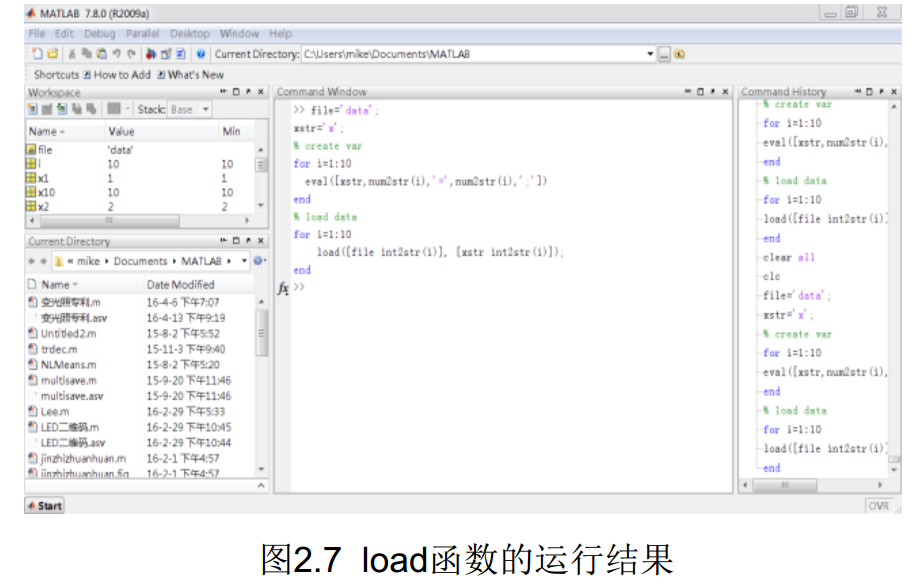

 `【例`**2-36**`】设`**A=[1 2 3; 4 5 6; 7 8 9]**`，抽取其中的第`**1**`、 `**2**`行，第`**1**`、 `**2**`列元素作为新的矩阵`**B**`。 `**MATLAB**`的代码如下：`  

A = [1 2 3; 4 5 6; 7 8 9];
B = A(1:2,1:2)

`【例`**2-37**`】设`**A=[1 2 3; 4 5 6; 7 8 9]**`，抽取其中的第`**1**`、 `**2**`行元素作为新的矩阵`**B**`。 `**MATLAB**`的代码如下：`

A = [1 2 3; 4 5 6; 7 8 9];
B = A(1:2,:)

  `【例`**2-38**`】设`**A=[1 2 3; 4 5 6; 7 8 9]**`，抽取其中的第`**1**`、 `**2**`列元素作为新的矩阵`**B**`。 `**MATLAB**`的代码如下：`  

A = [1 2 3; 4 5 6; 7 8 9];
B = A(:, 1:2)

`【例`**2-39**`】设`**A=[1 2 3; 4 5 6; 7 8 9]**`，抽取其中的第`**1**`， `**4**`个元素作为新矩阵`**B**`第`**1**`行，抽取第`**2,3**`个元素作为新矩阵`**B**`第`**2**`行。 `**MATLAB**`的代码如下：`  

A = [1 2 3; 4 5 6; 7 8 9];
B = [A([1 4]); A([2 3])]

`【例`**2-40**`】已知矩阵`**a**`，ᨀ取该矩阵的第一行第二列元素。`  

a=[1,2,3;3,4,5]
b=a(1,2)

`【例`**2-41**`】已知矩阵`**a**`，提取矩阵的第一行所有元素。`  

a=[1,2,3;3,4,5]
b=a(1, :)

`【例`**2-42**`】已知矩阵`**a**`，提取矩阵的第一列所有元素。`

a=[1,2,3;3,4,5]  
b=a(:,1)

`【例`**2-43**`】已知矩阵`**a**`，提取该矩阵的第一、二行所有元素`  

a=[1,2,3;3,4,5]
b=a([1,2],:)

`【例`**2-44**`】已知矩阵`**a**`，提取该矩阵的第一、三列所有元素`  

a=[1,2,3;3,4,5]
b=a(:,[1,3])

`【例`**2-45**`】已知矩阵`**a**`，ᨀ取该矩阵的第一、第二行和第一、第三列所有元素。`

a=[1,2,3;3,4,5]
b=a([1,2],[1,3])

`【例`**2-46**`】在`**MATLAB**`中， `**a**`（`**x**`， `**y**`）代表这个向量的`**x**`行`**y**`列的某个元素。在下面的例子中，我们将`**a**`的第二行，第三列赋予新的值，也就是把`**5**`换成`**-1**`。代码如下：`  

a=[1,2,3;3,4,5]
a(2,3)=-1

  `【例`**2-47**`】假设原来的矩阵`**cc**`是三行三列，下面我们用`**reshape**`进行重排。代码如下：`  

cc = [ 2 3 0; 0 5 5; 0 0 8]
g = reshape(cc, 1, 9)

`【例`**2-48**`】已知矩阵`**A=[1 2 3 4]**`，写出`**A**`复制`**6**`行的矩阵`**B**`。其`**MATLAB**`代码如下：`  

A = [1 2 3 4];
B = repmat(A, 6, 1)

`【例`**2-49**`】已知矩阵`**A=[1 2 3 4]**`，生成对矩阵`**A**`复制`**4**`行`**3**`列的矩阵`**B**`。其`**MATLAB**`代码如下：`  

A = [1 2 3 4];
B = repmat(A, 4, 3)

`【例`**2-50**`】例如 `**a=[1 2**`； `**3 4]**`，利用`**b=[a a+1; 5*a a]**`即可构建新的矩阵， `**4*4**`大矩阵。故`**MATLAB**`代码如下：`

a=[1 2;3 4];
b=[a a+1; 5*a a]

`【例`**2-51**`】例如`**A=[1 2**`； `**3 4]**`，删除矩阵`**A**`的第`**2**`行。故`**MATLAB**`代码如下：`

A = [1 2; 3 4];
A(2,:) = [];
A

`【例`**2-52**`】例如`**A=[1 2 0 0; 0 0 3 4; 0 0 0 0]**`，将矩阵`**A**`转换为稀疏矩阵`**S**`存储。`**MATLAB**`代码如下：`  

A=[1 2 0 0; 0 0 3 4; 0 0 0 0];
S = sparse(A);
S

  `【例`**2-53**`】例如`**A=[1 2 0 0; 0 0 3 4; 0 0 0 0]**`，将矩阵`**A**`转换为稀疏矩阵`**S**`存储，并显示然后恢复到正常的矩阵`**A**`。`**MATLAB**`代码如下：`  

A=[1 2 0 0; 0 0 3 4; 0 0 0 0];
S = sparse(A);
spy(S)
A = full(S)

`【例`**2-54**`】生成一个`**5**`阶魔方矩阵`**A**`。 `**MATLAB**`代码如下：`  

A = magic(5)

`【例`**2-55**`】以向量`**a=[1 2 3 4]**`生成一个范得蒙矩阵`**A**`。`

**MATLAB**`代码如下：`  

a=[1 2 3 4];
A = vander(a)

`【例`**2-56**`】求`**4**`阶希尔伯特矩阵`**A**`及其逆`**B**`。 `**MATLAB**`代码如下：`

A = hilb(4)
B = invhilb(4)

`【例`**2-57**`】以`**[1 2 3]**`为第一列， `**[3 4 5]**`为第一行生成托普利兹矩阵`**A**`。 `**MATLAB**`代码如下：`  

toeplitz([1 2 3], [3 4 5])

`【例`**2-58**`】已知矩阵`**A**`、 `**B**`，求两矩阵的和及差。 `**MATLAB**`代码如下：`  

A = [1 2 3;4 5 6];
B = [1 5 8 ;2 4 7];
C = A + B
D = A - B

`【例`**2-59**`】已知矩阵`**A**`、 `**B**`，求两矩阵的乘积。 `**MATLAB**`代码如下：`

A=[1 3 5;2 4 6];
B=[2 3 3;5 6 8;1 4 9];
D=A*B

`【例`**2-60**`】已知矩阵`**A**`、 `**B**`，求`**A\B**`和`**B/A**`。 `**MATLAB**`代码如下` 

A = [1 2;3 4];
B = [5 6;7 8];
C = A\B
D = B/A

`【例`**2-61**`】已知矩阵`**A = [1 2;3 4]**`，求`**A**`的`**3**`次幂。 `**MATLAB**

`代码如下：`  

A = [1 2;3 4];
B = A^3
C = A*A*A

`【例`**2-62**`】已知矩阵`**A = [1 2;3 4]**`和`**B=[1+i 2-i; 3 -i]**`，求矩阵`**A**`和`**B**`的转置。 `**MATLAB**`代码如下：`  

A = [1 2;3 4];
B = [1+i 2-i; 3 -i];
C = A';
D = B';
E = B.';
A
C
B
D
E

`【例`**2-63**`】已知矩阵`**A**`、 `**B**`，求两矩阵的点乘运算，并与矩阵乘法进行比较。 `**MATLAB**`代码如下：`  

A = [1 2 3;4 5 6; 1 1 0];
B = [1 5 8 ;2 4 7; 0 1 0];
C = A .* B
D = A * B

`【例`**2-64**`】已知矩阵`**A**`、 `**B**`，求两矩阵的点除运算。 `**MATLAB**`代码如下`  

A = [1 2 3;4 5 6];
B = [1 5 8 ;2 4 7];
C = A .\ B
D = A ./ B

  `【例`**2-65**`】已知矩阵`**A**`，求矩阵`**A**`的点幂运算。 `**MATLAB**`代码如下：`

A = [1 2 3;4 5 6];
B = A .^ 2

`【例`**2-66**`】已知矩阵`**A**`，求矩阵`**A**`与常数`**5**`的加减乘除和点乘、点除等运算。`**MATLAB**`代码如下：`  

A = [1 2 3;4 5 6];
B = A + 5
C = A - 5
D = A * 5
D1 = A .* 5
E = A / 5
E1 = A ./ 5
E2 = 5 \ A
F = A .\ 5

例2.5 建立矩阵A，然后找出在[10，20]区间的元素位置

A=[4,15,-45,10,6;56,0,17,-45,0]
find(A>=10&A<=20)

`【例`**2-67**`】举例比较两个数值的大小。 `**MATLAB**`代码如下：`  

3>5
3>1

`【例`**2-68**`】已知矩阵`**A**`、 `**B**`，比较这两个矩阵的大小。 `**MATLAB**`代码如下：`

A = [1 2 3;4 5 6];
B = [1 5 8 ;2 4 7];
C = A < B
D = A >= B
E = A == B
F = A ~= B

`【例`**2-69**`】已知矩阵`**A**`，用常数`**3**`对其进行比较。 `**MATLAB**`代码如下：`  

A = [1 2 3;4 5 6];
B = 3>A
C = A >= 3
D = A == 3

`【例`**2-70**`】举例说明逻辑运算。 `**MATLAB**`代码如下`  

0&0
0&1
3&2

`【例`**2-71**`】设`**a = 1**`，举例说明逻辑非运算。 `**MATLAB**`代码如下：`

a = 1;
b = ~a

  `【例`**2-72**`】已知矩阵`**A**`、 `**B**`，求矩阵`**A**`和`**B**`的逻辑运算。`**MATLAB**`代码如下：`  

A = [1 0 3;4 0 6]
B = [1 0 8 ;2 4 0]
C = A&B
D = A | B
E = ~A

`【例`**2-73**`】已知矩阵`**A**`，求`**3|A**`。 `**MATLAB**`代码如下：`  

A=[1 0 3; 4 0 6];
B = 3|A

`【例`**2-74**`】例如编写一段测试矩阵是不是全非`**0**`阵的测试函数。`**MATLAB**`代码如下：`  

a = [1 0 1; 0 1 1]
if all(a)
disp('The all element of matrix is not zero.');
else
disp('The matrix has zero element.');
end

`【例`**2-75**`】例如编写一段测试矩阵测试函数`**any**`。 `**MATLAB**`代码如下：`  

a = [1 0 1; 0 1 1]
any(a)

`【例`**2-76**`】例如编写一段测试矩阵测试函数`**find**`。 `**MATLAB**`代码如下：`  

a = zeros(4,5);
a(3, 2)=0.5
a(4,4)=-0.4
[i, j, v]=find(a)

`【例`**2-77**`】例如编写一段程序测试函数`**exist**`。 `**MATLAB**`代码如下：`  

if exist('sg.dat')
load sg.dat
else
sg=zeros(5,2)
end

`例子：`  

`建立一个字符串向量，然后对该向`

`量做如下处理：`

**(1) **`取第`**1**`～`**5**`个字符组成的子字符串。`

**(2) **`将字符串倒过来重新排列。`

**(3) **`将字符串中的小写字母变成相应`

`的大写字母，其余字符不变。`

**(4) **`统计字符串中小写字母的个数。`  

clc;
ch='ABc123d4e56Fg9' ;
disp(ch)
subch=ch(1:5) %取子字符串
revch=ch(end:-1:1) %将字符串倒排
k=find(ch>='a' & ch<='z') %找小写字母的位置
ch(k)= 'A'+(ch(k)-'a') %小写字母变成大写
ch
char(ch) %ASCII码矩阵转换为字符矩阵
length(k) %统计小写字母的个数
char([0:29;30:59;60:89;90:119;120:149])

`【例`**2-78**`】已知矩阵`**v**`，求其次对角线上所有元素。`**MATLAB**`代码如下：`  

v=[1 2 3 4;5 6 7 8;9 10 11 12]
A=diag(v,1)

`【例`**2-79**`】已知矩阵`**v**`，求其对角线元素。 `**MATLAB**`代码如下：`

v=[1 2 3 4;5 6 7 8;9 10 11 12]
A=diag(v,0)
B=diag(v)

`【例`**2-80**`】已知矩阵`**A**`，提取`**A**`的下三角部分。 `**MATLAB**`代码如下：`

A = [1 2 3; 5 6 7; 9 10 11 ]
L = tril(A)

  `【例`**2-81**`】已知矩阵`**A**`，提取`**A**`的第`**1**`， `**-1**`条对角线的以下部分。 `**MATLAB**`代码如下：`

A = [1 2 3 ;5 6 7 ;9 10 11]
L = tril(A,1)
L1 = tril(A,-1)

 `【例`**2-82**`】已知矩阵`**A**`，提取`**A**`的对角线以上部分。`**MATLAB**`代码如下：`  

v = [1 23 35; 67 47 89]
c = triu(v)

`【例`**2-83**`】已知矩阵`**A**`，提取`**A**`的第`**1**`， `**-1**`条对角线的以上部分。`**MATLAB**`代码如下：`  

A = [1 2 3 ;5 6 7 ;9 10 11]
L = triu (A,1)
L1 = triu (A,-1)

`【例`**2-84**`】已知矩阵`**A**`，求左右翻转的新矩阵。`  

A = [1 2 3; 3 4 2]
B = fliplr(A)

`【例`**2-85**`】已知矩阵`**A**`，求上下翻转以后的新矩阵`  

A = [1 2 3; 3 4 2]
B = flipud(A)

`【例`**2-86**`】已知矩阵`**A**`，用`**flipdim**`函数举例进行翻转。`  

A = [1 2 3; 4 5 6]
B = flipdim(A, 2)

`【例`**2-87**`】已知矩阵`**A**`，验证`**rot**`函数的功能。`  

A = [1 2 3; 4 5 6]
B = rot90(A)
B = rot90(A,-1)

`【例`**2-88**`】已知矩阵`**A,**`求该矩阵的逆。`  

A=[1:3; 4:6; 7:9]
inv(A)

`【例`**2-89**`】已知矩阵`**A,**`求该矩阵的伪逆。`  

A = [1 2 3; 1 2 3; 4 5 6]
B = inv(A)
C = pinv(A)

`【例`**2-90**`】求解矩阵的行列式。 `**MATLAB**`代码如下：`  

A = [1 2 3; 4 5 6; 7 8 9]
B = det(A)

`【例`**2-91**`】用`**magic**`函数生成矩阵`**m**`，求它的秩和迹。 `**MATLAB**`代码如下：`

m = magic(8)
t = trace(m)
k = rank(m)

`【例`**2-92**`】求向量`**a**`的范数。 `**MATLAB**`代码如下：`  

a = [1 2 3 4];
n = norm(a, inf)
n1 = norm(a, 1)
n2 = norm(a, 2)
n3 = norm(a, 0.5)

`【例`**2-93**`】已知一个矩阵`**A**`，求解`**A**`的范数。代码如下：`  

A=[1 2 3; 4 5 6]
n = norm(A)
n1 = norm(A,1)
n2 = norm(A, 'fro')

`【例`**2-94**`】已知矩阵`**A**`，求`**cond(A)**`。`  

A = [1 23 35; 67 47 89]
cond(A)

`【例`**2-95**`】已知矩阵`**A**`，利用`**eig**`函数可以快速求解该矩阵的特征值与特征向量。`

A = [1 2 4;
4 0 7
9 1 3];
[V,D] = eig(A)